## **T6.GA.P01. La carrera de la ardilla**

**Nombre: **Pablo Mendieta Ruiz

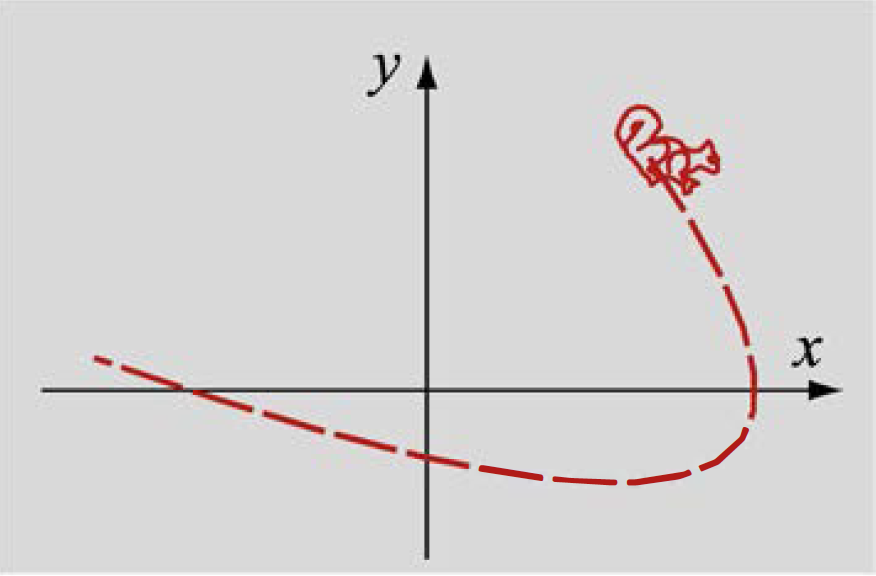

La posición de una ardilla (coordenadas $x$ e $y$ en metros) corriendo en función del tiempo, $t\;\left(\textrm{seg}\right)$, se da en la tabla siguiente. 

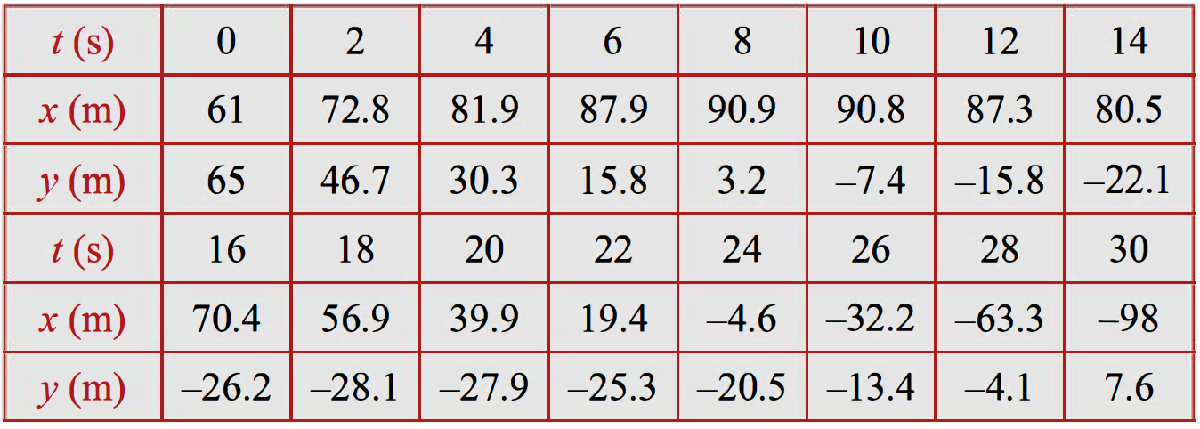

La velocidad de la ardilla, $v$, viene dada por $v=\sqrt{v_x^2 +v_y^2 }$ donde $v_x =\frac{\textrm{dx}}{\textrm{dt}}$, $v_y =\frac{\textrm{dy}}{\textrm{dt}}$, y la aceleración $a$ está dada por $a=\sqrt{a_x^2 +a_y^2 }$ donde $a_x =\frac{d^2 x}{dt^2 }$, $a_y =\frac{d^2 y}{dt^2 }$

a) (3p) Calcula la velocidad y la aceleración de la ardilla. Da el resultado en una tabla donde las columnas sean $x,y,t,v,a$

b) (2p) Representa gráficamente (en la misma gráfica) $v_x ,v_y$ y $v$ en función del tiempo

c) (2p) Representa gráficamente (en la misma gráfica )$a_x ,a_y$ y $a$ en función del tiempo

d) (3p) Calcula el momento en que la velocidad es mínima y cuánto es dicha velocidad mínima. Para ello calcula la derivada de $v$, represéntala gráficamente frente a $t$ mediante splines cúbicas y, a la vista de la gráfica, realiza interpolación inversa sobre tres puntos entre los que se encuentre la raíz buscada.

**Respuesta**

a) 

clc, clear 

% Datos del problema
t = 0 : 2 : 30;
x = [ 61, 72.8, 81.9, 87.9, 90.9, 90.8, 87.3, 80.5, 70.4, 56.9, 39.9, 19.4, -4.6, -32.2, -63.3, -98];
y = [65, 46.7, 30.3, 15.8, 3.2, -7.4, -15.8, -22.1, -26.2, -28.1, -27.9, -25.3, -20.5, -13.4, -4.1, 7.6];

$v=\sqrt{v_x^2 +v_y^2 }$ donde $v_x =\frac{\textrm{dx}}{\textrm{dt}}$, $v_y =\frac{\mathrm{dy}}{\mathrm{dt}}$

% Cálculo de las primeras y segundas derivadas en x. 
[xd,xdd] = PrimSegDeriv(t,x);
% Cálculo de las primeras y segundas derivadas en y. 
[yd,ydd] = PrimSegDeriv(t,y);

% Vx = xd ; Vy = yd
v = sqrt(xd.^2 + yd.^2);

$a=\sqrt{a_x^2 +a_y^2 }$ donde $a_x =\frac{d^2 x}{dt^2 }$, $a_y =\frac{d^2 y}{dt^2 }$

% ax = xdd ; ay = ydd
a = sqrt(xdd.^2 + ydd.^2);
% Tabla 
T = table(t', x', y', v', a');
T.Properties.VariableNames = {'t(s)','x(m)','y(m)' , 'v(m/s)', 'a(m/s^2)'}

T = 16×5 table
    t(s)    x(m)     y(m)     v(m/s)    a(m/s^2)
    ____    _____    _____    ______    ________

      0        61       65    10.887    0.82538 
      2      72.8     46.7    10.127    0.82538 
      4      81.9     30.3     8.598    0.90898 
      6      87.9     15.8    7.1388    0.88776 
      8      90.9      3.2    5.8451    0.92229 
     10      90.8     -7.4    4.8345     1.0124 
     12      87.3    -15.8    4.4873    0.97788 
     14      80.5    -22.1    4.9609    0.99153 
     16      70.4    -26.2    6.0877     1.0124 
     18      56.9    -28.1    7.6368     1.0204 
     20      39.9    -27.9    9.4011      1.061 
     22      19.4    -25.3    11.278     1.0335 
     24      -4.6    -20.5    13.239      1.068 
     26     -32.2    -13.4    15.237     1.0335 
     28     -63.3     -4.1    

b) 

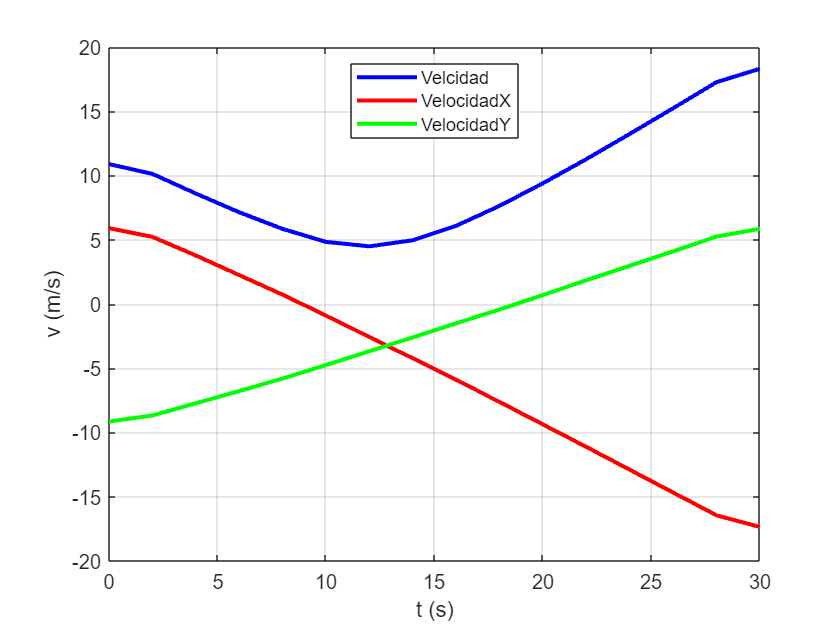

clf
% v
plot(t, v, 'b', 'LineWidth', 2)
hold on

% Vx
plot(t, xd, 'r', 'LineWidth', 2)

%Vy
plot(t, yd, 'g', 'LineWidth', 2)

ylabel('v (m/s)')
xlabel('t (s)')
grid on
legend('Velcidad','VelocidadX','VelocidadY',Location='north')

c) 

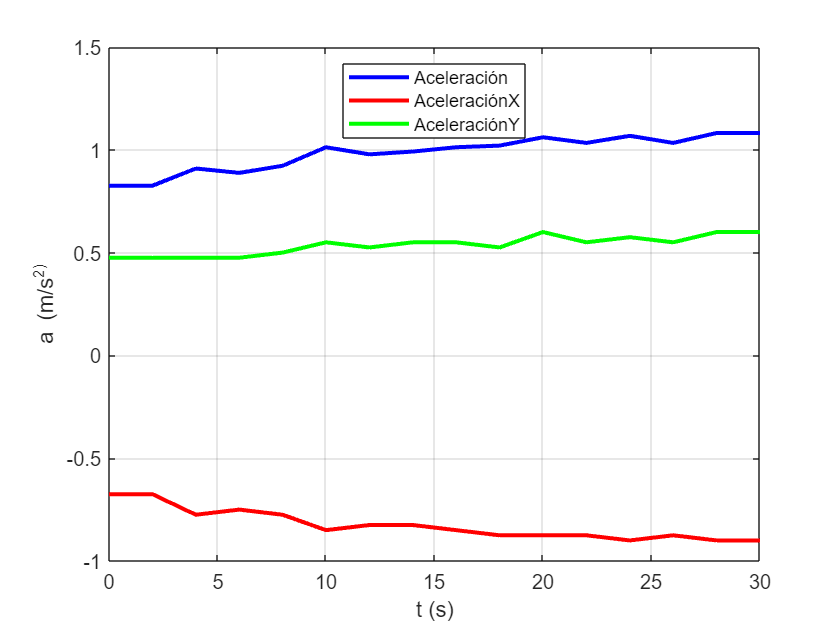

clf
% a
plot(t, a, 'b', 'LineWidth', 2)
hold on

% ax
plot(t, xdd, 'r', 'LineWidth', 2)

% ay
plot(t, ydd, 'g', 'LineWidth', 2)

ylabel('a (m/s^2)')
xlabel('t (s)')
grid on
legend('Aceleración','AceleraciónX','AceleraciónY',Location='north')

d) 

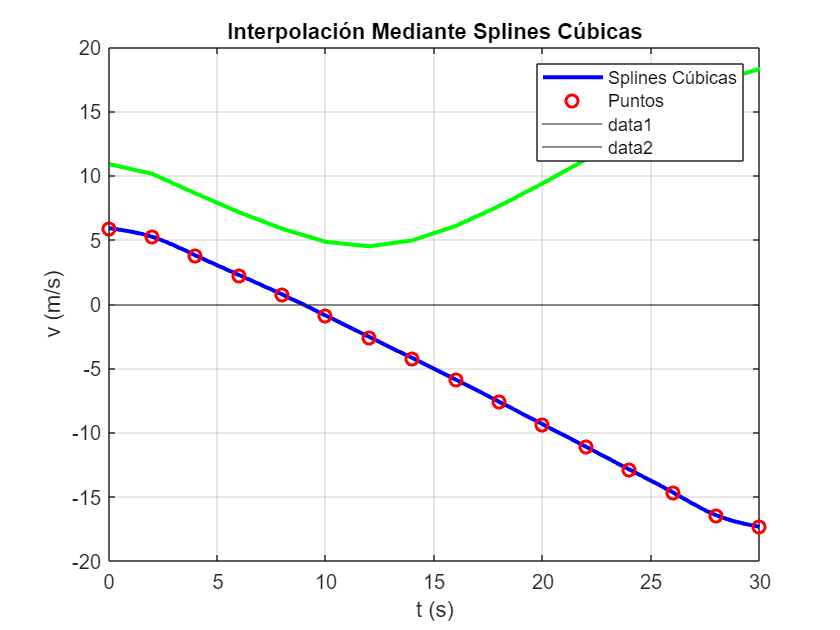

clf

% Cálculo de la derivada de la velocidad respecto al tiempo
[vd,~] = PrimSegDeriv(t,x);

% Cáclulo de los valores interpolados de y 
xp = linspace( t(1), t(length(t) ), 100);
yp = zeros(1,100);
for i = 1:100
    yp(i) =  SplineCub(t,vd,xp(i));
end   

% v
plot(xp,yp,'b','LineWidth',2)
hold on
plot(t, vd, 'or', 'LineWidth',1.5)
title('Interpolación Mediante Splines Cúbicas')
legend('Splines Cúbicas','Puntos',Location='northeast')
yline(0)
xline(0)
ylabel('v (m/s)')
xlabel('t (s)')
grid on 

Observando la gráfica, vemos que la raíz se encuentra entre los valores de $t=6,8,10$

% Interpolación inversa sobre los 3 puntos más cercanos a la raíz 
clf
tiempos = [6, 8, 10];

% Buscamos las posiciones de los tiempos elegidos en el vector t. 
posiciones = zeros(size(tiempos)); 
for i = 1:length(tiempos)
    tiempo = tiempos(i);
    for j = 1:length(t)
        if t(j) == tiempo
            posiciones(i) = j; 
            break
        end
    end
end

t3 = [t(posiciones(1)), t(posiciones(2)), t(posiciones(3))];
vd3 = [vd(posiciones(1)), vd(posiciones(2)), vd(posiciones(3))];
raizY = 0;

% Interpolación inversa 
raizX = interp1(vd3, t3, raizY);
raizy = SplineCub(t3,vd3, raizX);

fprintf('El tiempo correspondiente para x=0 (velocidad mínima): %f s\n', raizX);

El tiempo correspondiente para x=0 (velocidad mínima): 8.892308 s


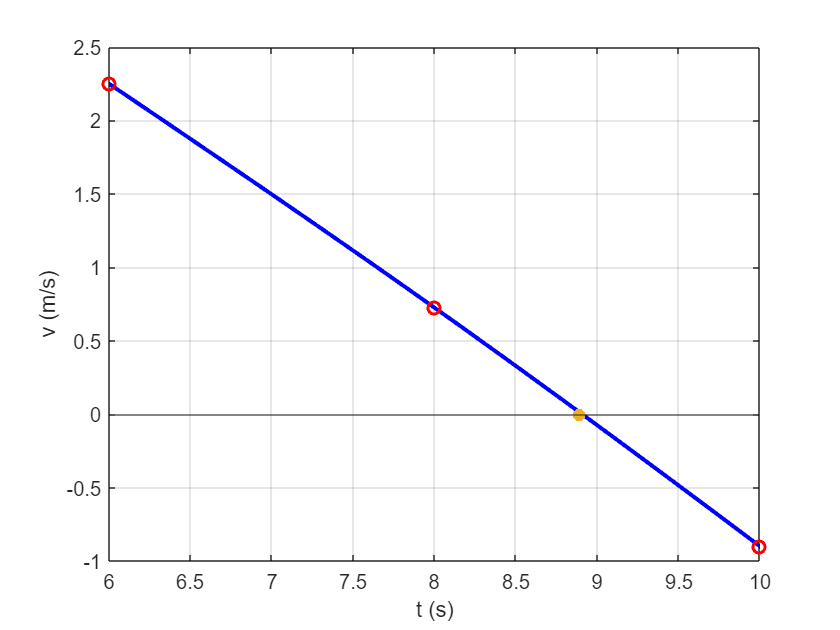

plot(xp,yp,'b','LineWidth',2)
hold on
xlim([t(posiciones(1)), t(posiciones(3))]);
plot(t3, vd3, 'or', 'LineWidth',1.5)
grid on 
x_punto = raizX;
y_punto = raizY;
yline(0)
plot(x_punto, y_punto, '*', 'LineWidth', 3)
ylabel('v (m/s)')
xlabel('t (s)')